## ECE 537 : Assignment 2

Group 9 - Ashlynn Steeves, Derrell D'Souza

%close all;
%clear all;
%clc;


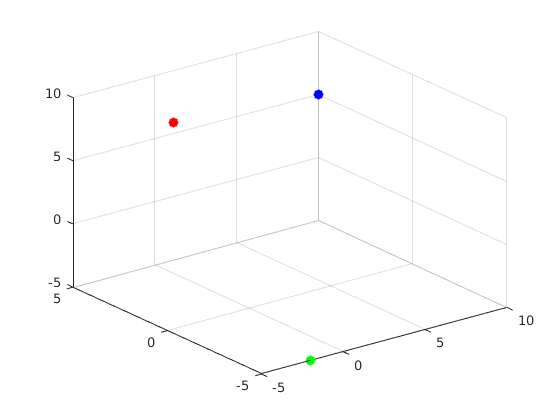

scatter3(0, 4, 7, '*r', 'LineWidth', 5.0)
hold on; 
scatter3(10, 5, 5, '*b', 'LineWidth', 5.0)
scatter3(-2, -5, -5, '*g', 'LineWidth', 5.0)
hold off; 

t_AB = sqrt((0-10)^2+(4-5)^2+(7-5)^2)
t_AC = sqrt((0-(-2))^2+(4-(-5))^2+(7-(-5))^2)
t_BC = sqrt((10-(-2))^2+(5-(-5))^2+(5-(-5))^2)


scatter3(2, 2, 7, '*r', 'LineWidth', 5.0)

t_AB = 10.2470

hold on; 

t_AC = 15.1327

scatter3(8, 3, 5, '*b', 'LineWidth', 5.0)

t_BC = 18.5472

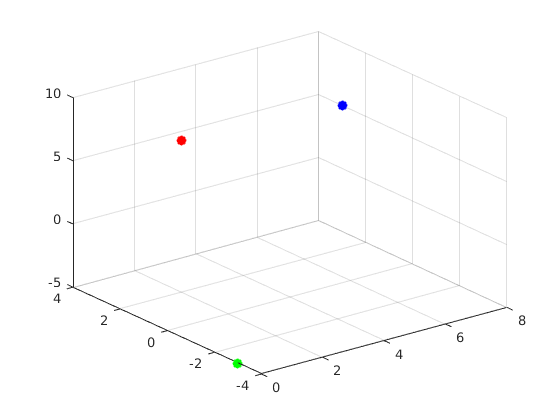

scatter3(0, -3, -5, '*g', 'LineWidth', 5.0)
hold off; 

t_AB = sqrt((2-4)^2+(-5)^2+(7-5)^2)
t_AC = sqrt((2-(-2))^2+(4-(-5))^2+(7-(-5))^2)
t_BC = sqrt((10-(-2))^2+(5-(-5))^2+(5-(-5))^2)

**Task 1** - Reload the Class A, B and C data from Exercise 1 and generated the Bayes decision boundaries for equal a priori class probabilities.

K = 1000;

t_AB = 5.7446

D = 3;

t_AC = 15.5242

t_BC = 18.5472

% Dataset A
mu_A = [0 4 7];
sigma_A = [6.5000 2.1651 1.2500 ; 2.1651 5.1250 2.3816;1.2500 2.3816 2.3750];
data_A = gaussian_data_from_ss(K,D,mu_A,sigma_A);

% Dataset B
mu_B = [10 5 5];
sigma_B = [3.0184 0.4331 -1.4481; 0.4331 0.9436 -0.6456 ;-1.4481 -0.6456 1.2880];
data_B = gaussian_data_from_ss(K,D,mu_B,sigma_B);

% Dataset C
mu_C = [-2 -5 -5];
sigma_C = [6.8928 -1.3750 3.1945 ;-1.3750 3.3572 0.6945;3.1945 0.6945 3.7500];
data_C = gaussian_data_from_ss(K,D,mu_C,sigma_C);

Vaxis = [-15 15 -15 15 -15 15];
volume = vol3D(Vaxis, 100);

pdfA = gaus_pdf(data_A, volume); % A vector of probabilities that each point is from Class A
pdfB = gaus_pdf(data_B, volume); % A vector of probabilities that each point is from Class B
pdfC = gaus_pdf(data_C, volume); % A vector of probabilities that each point is from Class C

t1_priors = [1/3 1/3 1/3]; % Apriori probabilites for each class 
[t1_classified_pts, t1_gA, t1_gB, t1_gC] = gaus_discriminant_classifier(pdfA, pdfB, pdfC, volume, t1_priors); % A matrix where the first three columns are respectivley an x, y and z coordinate and the fourth column is the classification of the point

[t1_b_AB, t1_b_BC, t1_b_AC] = boundaries(t1_gA, t1_gB, t1_gC,volume);
t1_title = 'Task 1 - All Class Decision Boundaries';
x = plot(data_A, data_B, data_C, t1_b_AB, t1_b_AC, t1_b_BC, t1_title);


**Task 2** - Assess the degree to which changes to the means and covariance of the data classes produces changes the nature of the generated inter-class Bayes decision boundaries.

t1_title = 'Task 1 - All Class Decision Boundaries'

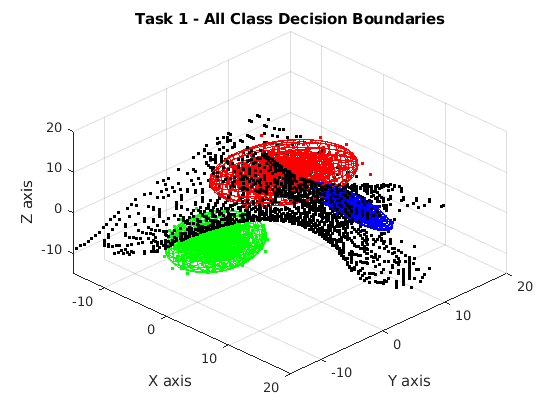

%derrell 



**Task 3 **- Show the nature of these changes by plotting the 3 data classes and their respective decision boundaries with the same 3-D plot.

% plots 


**Task 4** - Assess how these decision boundaries change with changes to the three class’s a priori probabilities.

Solution: 

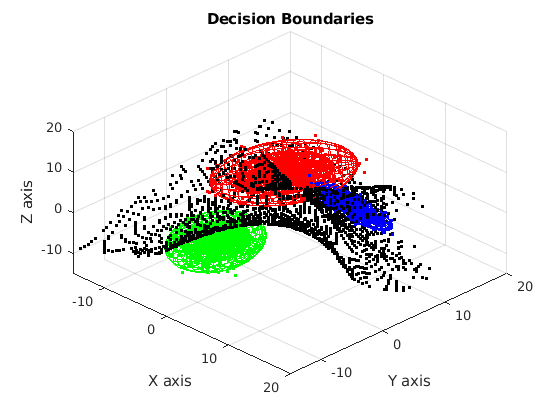

% Test case 1 
% A priori probabilities are skewed greatly towards Class A 
t4_1_priors = [7/8 1/16 1/16]; % Apriori probabilites for each class 
[t4_1_classified_pts, t4_1_gA, t4_1_gB, t4_1_gC] = gaus_discriminant_classifier(pdfA, pdfB, pdfC, volume, t4_1_priors);
[t4_1_b_AB, t4_1_b_BC, t4_1_b_AC] = boundaries(t4_1_gA, t4_1_gB, t4_1_gC,volume);
t4_1_title = 'Task 4 - Test Case 1'
x = plot(data_A, data_B, data_C, t4_1_b_AB, t4_1_b_AC, t4_1_b_BC, t4_1_title);

% Test case 2 
% A priori probabilities are skewed greatly towards Class B
t4_2_priors = [1/16 7/8 1/16]; % Apriori probabilites for each class 
[t4_2_classified_pts, t4_2_gA, t4_2_gB, t4_2_gC] = gaus_discriminant_classifier(pdfA, pdfB, pdfC, volume, t4_2_priors);
[t4_2_b_AB, t4_2_b_BC, t4_2_b_AC] = boundaries(t4_2_gA, t4_2_gB, t4_2_gC,volume);
t4_2_title = 'Task 4 - Test Case 2'
x = plot(data_A, data_B, data_C, t4_2_b_AB, t4_2_b_AC, t4_2_b_BC, t4_2_title);

% Test case 3
% A priori probabilities are skewed greatly towards Class C
t4_3_priors = [1/16 1/16 7/8]; % Apriori probabilites for each class 
[t4_3_classified_pts, t4_3_gA, t4_3_gB, t4_3_gC] = gaus_discriminant_classifier(pdfA, pdfB, pdfC, volume, t4_3_priors);

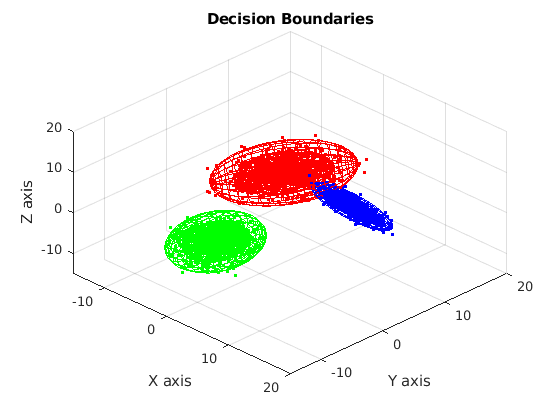

[t4_3_b_AB, t4_3_b_BC, t4_3_b_AC] = boundaries(t4_3_gA, t4_3_gB, t4_3_gC,volume);
t4_3_title = 'Task 4 - Test Case 3'
x = plot(data_A, data_B, data_C, t4_3_b_AB, t4_3_b_AC, t4_3_b_BC);


%%SHMUSH EM TOGETHER FIRST

% Test case 4 

% A priori probabilities are skewed greatly towards Class A 
t4_4_priors = [7/8 1/16 1/16]; % Apriori probabilites for each class 
[t4_4_classified_pts, t4_4_gA, t4_4_gB, t4_4_gC] = gaus_discriminant_classifier(pdfA, pdfB, pdfC, volume, t4_4_priors);
[t4_4_b_AB, t4_4_b_BC, t4_4_b_AC] = boundaries(t4_4_gA, t4_4_gB, t4_4_gC,volume);
t4_4_title = 'Task 4 - Test Case 1'
x = plot(data_A_t4, data_B, data_C, t4_4_b_AB, t4_4_b_AC, t4_4_b_BC, t4_4_title);

% Test case 5
% A priori probabilities are skewed greatly towards Class B
t4_5_priors = [1/16 7/8 1/16]; % Apriori probabilites for each class 
[t4_5_classified_pts, t4_5_gA, t4_5_gB, t4_5_gC] = gaus_discriminant_classifier(pdfA, pdfB, pdfC, volume, t4_5_priors);
[t4_5_b_AB, t4_5_b_BC, t4_5_b_AC] = boundaries(t4_5_gA, t4_5_gB, t4_5_gC,volume);
t4_5_title = 'Task 4 - Test Case 2'
x = plot(data_A, data_B, data_C, t4_5_b_AB, t4_5_b_AC, t4_5_b_BC, t4_5_title);

% Test case 6
% A priori probabilities are skewed greatly towards Class C
t4_6_priors = [1/16 1/16 7/8]; % Apriori probabilites for each class 
[t4_6_classified_pts, t4_6_gA, t4_6_gB, t4_6_gC] = gaus_discriminant_classifier(pdfA, pdfB, pdfC, volume, t4_6_priors);
[t4_6_b_AB, t4_6_b_BC, t4_6_b_AC] = boundaries(t4_6_gA, t4_6_gB, t4_6_gC,volume);
t4_6_title = 'Task 4 - Test Case 3'
x = plot(data_A, data_B, data_C, t4_6_b_AB, t4_6_b_AC, t4_6_b_BC);



** Comments: **

We can see with the original dataset that changes to the a priori probability, unless taken to the extreme, do not have much of an impact on the decision boundaries (as seen in test cases 1-3). This is because the original decision boundaries lie quite far away (at least 3 standard deviations) from the mean of the original datasets . If we adjust the datasets to be closer together such that the decison boundaries are within XXX standard deviations of the mean ( as seen in test cases 4-6) we notice that the decision boundaries become much more sensitive to changes in the a priori probabilies. 

**Task 5 **-  Assess how these decision boundaries change with changes to the classes λAA, λAB, λAC, λBB, λBC, and, λCC loss functions, assuming λAB = λBA, λAC = λCA and λBC = λCB.

% Derrell 

**Task 6 ** -  Now introduce outlier data points to one of the classes at a 10, 50, and 100 standard deviation (in what direction???) Mahalanobis distance from that class’s mean and regenerate the Bayes class boundaries.

         • Discuss the impacts that such single outlier data points can have on the resulting nature of the inter-class Bayes decision boundaries.

% Adding these points to Class A 
t6_priors = [1/3 1/3 1/3]

pt_mal_10 = additional_pts(mu_A, sigma_A, 10)'; % Finding a point at the desired mahalanobis distance 
class_A_p10 = [data_A;pt_mal_10]; % Adding the new point to the original dataset A 
%pdfA_p10 = gaus_pdf(class_A_p10, volume); % Calculating the pdf for the new dataset 
%classified_pts_p10 = gaus_discriminant_classifier(pdfA_p10,pdfB, pdfC, volume, t6_priors) % Using the discriminant function to classify the points in the new dataset 

pt_mal_50 = additional_pts(mu_A, sigma_A, 50)'; % Finding a point at the desired mahalanobis distance 
class_A_p50 = [data_A;pt_mal_50]; % Adding the new point to the original dataset A 
%pdfA_p50 = gaus_pdf(class_A_p50, volume); % Calculating the pdf for the new dataset
%classified_pts_p50 = gaus_discriminant_classifier(pdfA_p50,pdfB, pdfC, volume, t6_priors)% Using the discriminant function to classify the points in the new dataset 

pt_mal_100 = additional_pts(mu_A, sigma_A, 100)'; % Finding a point at the desired mahalanobis distance 
class_A_p100 = [data_A;pt_mal_100] % Adding the new point to the original dataset A 
%pdfA_p100 = gaus_pdf(class_A_p100, volume); % Calculating the pdf for the new dataset 
%classified_pts_p100 = gaus_discriminant_classifier(pdfA_p100,pdfB, pdfC, volume, t6_priors) % Using the discriminant function to classify the points in the new dataset 


**Task 7** -  For real-world data analysis problems, 

(a) Could the nature of the class decision boundaries effective be driven by only a few data points within the data?

(b) Is it correct (or appropriate) to have decision boundaries that exhibit high sensitivities to only a small number of data samples?

(c) How would you detect this? 

(d) How would you resolve this?

function[new_pt] = additional_pts(mu, sigma, desired_mah)
    [V, D] = eig(sigma);

    principal_axes = sqrt(desired_mah)*((V)*sqrt(D))+mu'; % Principal axes extended to the appropriate length to acheive desired mahalanobis disance
    new_pt = principal_axes(:,1); % Choosing the new point along the 1st principal axes ( this choice is arbatrary)    

t6_priors =     0.3333    0.3333    0.3333



end

function[classified_pts, discA, discB, discC] = gaus_discriminant_classifier(pdfA,pdfB, pdfC, pts, prior)
    discA = log(pdfA)+log(prior(1)); % Calculate the discriminant for points belonging to Class A
    discB = log(pdfB)+log(prior(2)); % Calculate the discriminant for points belonging to Class B
    discC = log(pdfC)+log(prior(3)); % Calculate the discriminant for points belonging to Class C
    
    desc_matrix = [discA discB discC]; % Merging all discriminant values into a matrix
    [~, I] = max(desc_matrix,[], 2); % Returning the index of the largest discriminant value per row 
    % Index 1 corresponds to the point being classified as Class A, index 2
    % is Class B and index 3 is Class C.
    

class_A_p100 =     1.1899    5.7898    7.4564
   -0.9292    8.0049    9.8162
    2.2611    0.9641    7.4877
   -2.5480    4.5480    7.1170
    0.5306    4.8493    6.7731
    0.3609    1.9185    7.5873
   -1.6878    2.5215    7.2555
    2.3294    6.3037    8.5822
   -4.4453    9.1056    7.9614
   -0.6946    9.6281    8.9407


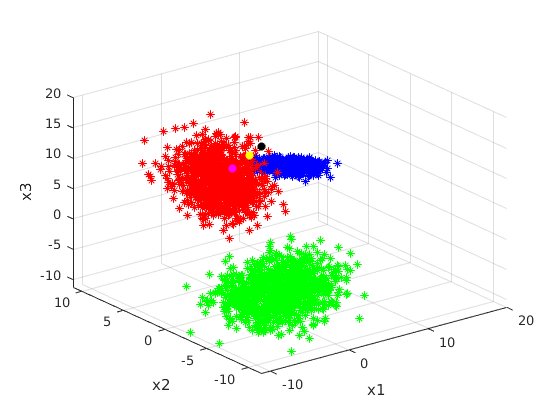

    classified_pts = [pts I]; % Appending the classification of each point to the points themselves 
end 



function[pdf] = gaus_pdf(class ,pts)
    mu = mean(class); % Calculating the mean of the given class
    
    sigma = cov(class); % Calculating the covarriance of the given class
    sigma_inv = inv(sigma); % Calculating the inverse of the covarriance
    
    d = length(mu); % Determining the dimensionality of the data
    
    xmmu = pts-mu; % Subtracting the mean from each point in the dataset
    norm = (1/((2*pi)^(d/2)))*(det(sigma)^(-1/2)); % Calculating the normalization constant (from the multivarriate gaussian eq)
    exp_term = zeros(length(xmmu),1); % Initializing the vector of exponential terms 
    
    for i = 1:length(xmmu)
        exp_term(i) = -1/2*xmmu(i,:)*sigma_inv*xmmu(i,:)'; % Calculating the term that will be in the exponent (from the multivarriate gaussian eq) for each datapoint
    end
    
    pdf = norm*exp(exp_term); % Combining terms to generate the probability that a point is from the given class
end


function f = gaussian_data_from_ss(K,D,mu,sigma)
    N = randn(K,D); % Generate a subset of K D-dimensional samples from a normal distribution
    N_c = N - mean(N); % Centralize the data at zero-mean
    
    [v,d] = eig(cov(N_c)); % Obtain eigen values and eigen vectors for covariance of N    
    R = v*inv(sqrt(d)); % Generate the whitening transform
    W  = N_c*R; % Apply the whitening transform on the centralized data
    
    [vn,dn] = eig(sigma); % Obtain eigen values and eigen vectors of the desired covariance
    R_inv = sqrt(dn)*inv(vn); % Generate the inverse whitening transform
    f = W*R_inv; % Apply the inverse whitening transfrom on the whitened gaussian data 
    f = f + mu; % Centralize the data at the desired mu
end 

function V = vol3D(Vaxis,Num) 
    NV = Num;
    
    if length(Vaxis) == 2
        Vaxis = [Vaxis Vaxis Vaxis];
    end
    
    min_a = Vaxis(1);
    max_a = Vaxis(2);
    res = (max_a-min_a)/(NV-1);
    
    r = min_a:res:max_a;
    r = r(:);
    
    rx = [Vaxis(1):(Vaxis(2)-Vaxis(1))/(NV-1):Vaxis(2)]';
    ry = [Vaxis(3):(Vaxis(4)-Vaxis(3))/(NV-1):Vaxis(4)]';
    rz = [Vaxis(5):(Vaxis(6)-Vaxis(5))/(NV-1):Vaxis(6)]';
    
    x = zeros(3,length(rz)^3);
    k =1;
    j = 1;
    for i = 1:length(rz):length(x)
        x(3,(i-1)+(1:length(rz)))= rz;
        x(2,(i-1)+(1:length(rz))) = ry(k)*ones(1,length(rz));
        x(1,(i-1)+(1:length(rz))) = rx(j)*ones(1,length(rz));
        k = k+1;
        if k > length(rz)
            k =1;
            j = j +1;
        end
    end
    x = x';
    V = x;

end

function [b_AB, b_BC, b_AC] = boundaries(gA, gB, gC,V)
    %pairwise testing has to be done between two classes than have g higher
    %than the third
    indxAB = find((gA>gB & gB>gC)|(gB>gA & gA>gC));
    indxBC = find((gB>gC & gC>gA)|(gC>gB & gB>gA));
    indxAC = find((gA>gC & gC>gB)|(gC>gA & gA>gB));
    
    gAB = abs(gA(indxAB) - gB(indxAB));
    gBC = abs(gB(indxBC) - gC(indxBC));
    gAC = abs(gA(indxAC) - gC(indxAC));
    
    %tolerence 0.1
    indxAB_n = find(gAB<0.1);
    indxBC_n = find(gBC<0.1);
    indxAC_n = find(gAC<0.1);
    indxAB = indxAB(indxAB_n);
    indxBC = indxBC(indxBC_n);
    indxAC = indxAC(indxAC_n);
    
    b_AB = V(indxAB,:);
    b_BC = V(indxBC,:);
    b_AC = V(indxAC,:);

end

function [x1,y1,z1,x2,y2,z2,x3,y3,z3] = ellipse_cord(data)

    mu = mean(data);
    sigma = cov(data);
    [v,d] = eig(sigma);
    %plot ellipsoid for three standard deviations and zero mean
    radius = sqrt(diag(d));
    [x1,y1,z1] = ellipsoid(0, 0, 0, radius(1),radius(2),radius(3));
    [x2,y2,z2] = ellipsoid(0, 0, 0, 2*radius(1),2*radius(2),2*radius(3));
    [x3,y3,z3] = ellipsoid(0, 0, 0, 3*radius(1),3*radius(2),3*radius(3));
    
    %rotate ellipsoids
    x1 = kron(v(:,1),x1);y1 = kron(v(:,2),y1);z1 = kron(v(:,3),z1);
    x2 = kron(v(:,1),x2);y2 = kron(v(:,2),y2);z2 = kron(v(:,3),z2);
    x3 = kron(v(:,1),x3);y3 = kron(v(:,2),y3);z3 = kron(v(:,3),z3);
    dat1 = x1 + y1 + z1; dat2 = x2 + y2 + z2 ; dat3 = x3 + y3 + z3; % to account for rotation of all three axis 
    n = size(dat1,2);
    
    %shift the ellipsoids
    x1 = dat1(1:n,:) + mu(1); y1 = dat1(n+1:2*n,:) + mu(2); z1 = dat1(2*n+1:end,:) + mu(3); 
    x2 = dat2(1:n,:) + mu(1); y2 = dat2(n+1:2*n,:) + mu(2); z2 = dat2(2*n+1:end,:) + mu(3);
    x3 = dat3(1:n,:) + mu(1); y3 = dat3(n+1:2*n,:) + mu(2); z3 = dat3(2*n+1:end,:) + mu(3);
       
end 

function [x] = plot(data_A, data_B, data_C, b_AB, b_AC, b_BC, title_)

    figure()
    axes_plot = axes;
    hold(axes_plot,'on');
    
    [xA1,yA1,zA1,xA2,yA2,zA2,xA3,yA3,zA3] = ellipse_cord(data_A);
    A1 = surf(xA1, yA1, zA1,'EdgeColor', 'r','FaceAlpha',0);
    A2 = surf(xA2, yA2, zA2, 'EdgeColor', 'r','FaceAlpha',0);
    A3 = surf(xA3, yA3, zA3,'EdgeColor', 'r','FaceAlpha',0);
    
    [xB1,yB1,zB1,xB2,yB2,zB2,xB3,yB3,zB3] = ellipse_cord(data_B);
    B1 = surf(xB1, yB1, zB1,'EdgeColor', 'b','FaceAlpha',0);
    B2 = surf(xB2, yB2, zB2, 'EdgeColor', 'b','FaceAlpha',0);
    B3 = surf(xB3, yB3, zB3,'EdgeColor', 'b','FaceAlpha',0);
    
    [xC1,yC1,zC1,xC2,yC2,zC2,xC3,yC3,zC3] = ellipse_cord(data_C);
    C1 = surf(xC1, yC1, zC1,'EdgeColor', 'g','FaceAlpha',0); 
    C2 = surf(xC2, yC2, zC2, 'EdgeColor', 'g','FaceAlpha',0);
    C3 = surf(xC3, yC3, zC3,'EdgeColor', 'g','FaceAlpha',0);
    
    plot3(data_A(:,1),data_A(:,2),data_A(:,3),'color','r','Marker','.','LineStyle','none')
    plot3(data_B(:,1),data_B(:,2),data_B(:,3),'color','b','Marker','.','LineStyle','none')
    plot3(data_C(:,1),data_C(:,2),data_C(:,3),'color','g','Marker','.','LineStyle','none')
    
    % Plotting decision boundaries
    plot3(b_AB(:,1),b_AB(:,2),b_AB(:,3),'Marker','.','LineStyle','none','Color','k');
    plot3(b_BC(:,1),b_BC(:,2),b_BC(:,3),'Marker','.','LineStyle','none','Color','k');
    plot3(b_AC(:,1),b_AC(:,2),b_AC(:,3),'Marker','.','LineStyle','none','Color','k');
    
    % Labeling axes
    zlabel('Z axis');
    ylabel('Y axis');
    xlabel('X axis');
    
    % Creating title
    title(title_);
    xlim(axes_plot,[-15 20]);
    ylim(axes_plot,[-15 20]);
    zlim(axes_plot,[-15 20]);
    view(axes_plot,[45 45]);
    grid(axes_plot,'on');
    hold(axes_plot,'off');
    
    x = 0; 

end 
